clear all;
clf;
sub = rossubscriber('/stable_scan');
% Collect data at the room origin
scan_message = receive(sub);
r = scan_message.Ranges(1:end-1);
d = .1;
n = 100; 
theta = [0:359]';
[r,theta] = cleandata(r,theta);
[r, theta] = splitDataSet(r,theta);

temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 221×1 single column vector
    1.6590
    1.5820
    1.5730
    1.5370
    1.6510
    1.6330
    1.6390
    1.6340
    1.6440
    1.6490


theta =      9
    10
    11
    12
    17
    18
    19
    20
    21
    22


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 219×1 single column vector
    1.5730
    1.5370
    1.6510
    1.6330
    1.6390
    1.6340
    1.6440
    1.6490
    1.6630
    1.6780


theta =     11
    12
    17
    18
    19
    20
    21
    22
    23
    24


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 217×1 single column vector
    1.6510
    1.6330
    1.6390
    1.6340
    1.6440
    1.6490
    1.6630
    1.6780
    2.2390
    2.3080


theta =     17
    18
    19
    20
    21
    22
    23
    24
    42
    44


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 205×1 single column vector
    2.4020
    2.4360
    2.4860
    1.0890
    1.0720
    1.0550
    1.0400
    1.0250
    1.0120
    0.9990


theta =     47
    48
    49
    51
    52
    53
    54
    55
    56
    57


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 201×1 single column vector
    1.0720
    1.0550
    1.0400
    1.0250
    1.0120
    0.9990
    0.9860
    0.9740
    0.9620
    0.9490


theta =     52
    53
    54
    55
    56
    57
    58
    59
    60
    61


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 177×1 single column vector
    2.5360
    2.5090
    1.8320
    1.8050
    1.7900
    1.7770
    1.7820
    1.7770
    1.7570
    2.3130


theta =     77
    78
    79
    80
    81
    82
    83
    84
    85
    86


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 175×1 single column vector
    1.8320
    1.8050
    1.7900
    1.7770
    1.7820
    1.7770
    1.7570
    2.3130
    2.5050
    2.5080


theta =     79
    80
    81
    82
    83
    84
    85
    86
    93
    94


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 173×1 single column vector
    1.7900
    1.7770
    1.7820
    1.7770
    1.7570
    2.3130
    2.5050
    2.5080
    2.4650
    2.4450


theta =     81
    82
    83
    84
    85
    86
    93
    94
    95
    96


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 168×1 single column vector
    2.3130
    2.5050
    2.5080
    2.4650
    2.4450
    2.4460
    1.4140
    1.4020
    1.3900
    1.3750


theta =     86
    93
    94
    95
    96
    97
    99
   100
   101
   102


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 164×1 single column vector
    2.4450
    2.4460
    1.4140
    1.4020
    1.3900
    1.3750
    1.3630
    1.3510
    1.3420
    1.3290


theta =     96
    97
    99
   100
   101
   102
   103
   104
   105
   106


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 161×1 single column vector
    1.4020
    1.3900
    1.3750
    1.3630
    1.3510
    1.3420
    1.3290
    1.3180
    1.3080
    1.3000


theta =    100
   101
   102
   103
   104
   105
   106
   107
   108
   109


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 145×1 single column vector
    1.8360
    1.7470
    1.6920
    1.4950
    1.4200
    1.3870
    1.3530
    1.3210
    1.2890
    1.2590


theta =    116
   117
   118
   124
   126
   127
   128
   129
   130
   131


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 143×1 single column vector
    1.6920
    1.4950
    1.4200
    1.3870
    1.3530
    1.3210
    1.2890
    1.2590
    1.2330
    1.2030


theta =    118
   124
   126
   127
   128
   129
   130
   131
   132
   133


temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


temp_thetas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r = 141×1 single column vector
    1.4200
    1.3870
    1.3530
    1.3210
    1.2890
    1.2590
    1.2330
    1.2030
    1.1820
    1.1570


theta =    126
   127
   128
   129
   130
   131
   132
   133
   134
   135


x = r.*cosd(theta);
y = r.*sind(theta);
for j = 1:14
    plot(x(j,:), y(j,:), '.')
    hold on;
   
end

indx = zeros(1, 14);
for g = 1:14
    for l = 3: length(r)-1
        if r(g,l) == 0
            indx(g) = l;
            break
        end
    end
end
XC = zeros(1,14)

XC =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


YC = zeros(1,14)

YC =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


RR = zeros(1,14)

RR =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


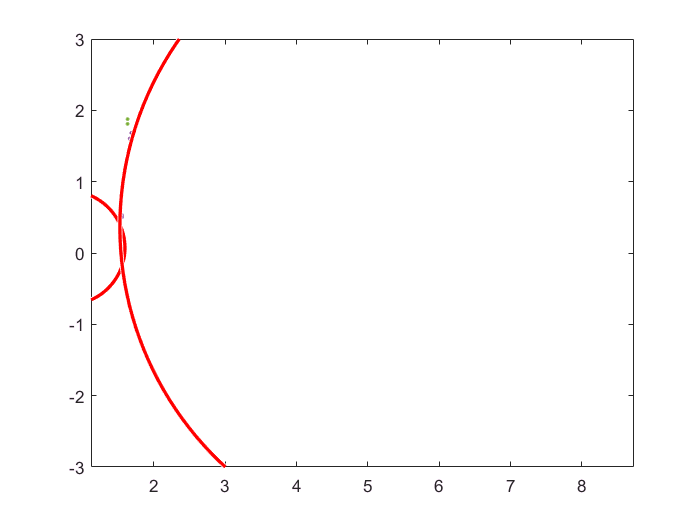

A = 0.1330

B = -0.2114

C = -0.0194

D = 0

X = 0.7948

Y = 0.0729

R = 0.7982

X = 0.7948

Y = 0.0729

R = 0.7982

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948         0         0         0         0         0         0         0         0         0         0         0         0         0


YC =     0.0729         0         0         0         0         0         0         0         0         0         0         0         0         0


RR =     0.7982         0         0         0         0         0         0         0         0         0         0         0         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN         0         0         0         0         0         0         0         0         0         0         0         0


YC =     0.0729       NaN         0         0         0         0         0         0         0         0         0         0         0         0


RR =     0.7982       NaN         0         0         0         0         0         0         0         0         0         0         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0


YC =     0.0729       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0


RR =     0.7982       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0


A = 0.0052

B = -0.0636

C = -0.0038

D = 0.0855

X = 6.0977

Y = 0.3679

R = 4.5756

X = 6.0977

Y = 0.3679

R = 4.5756

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0         0         0         0         0         0         0         0         0         0


YC =     0.0729       NaN       NaN    0.3679         0         0         0         0         0         0         0         0         0         0


RR =     0.7982       NaN       NaN    4.5756         0         0         0         0         0         0         0         0         0         0


A = 4.4409e-16

B = 0

C = 0

D = 0

X = 0

Y = 0

R = 0

X = 0

Y = 0

R = 0

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0         0         0         0         0         0         0         0         0         0


YC =     0.0729       NaN       NaN    0.3679         0         0         0         0         0         0         0         0         0         0


RR =     0.7982       NaN       NaN    4.5756         0         0         0         0         0         0         0         0         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN         0         0         0         0         0         0         0         0


YC =     0.0729       NaN       NaN    0.3679         0       NaN         0         0         0         0         0         0         0         0


RR =     0.7982       NaN       NaN    4.5756         0       NaN         0         0         0         0         0         0         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN       NaN         0         0         0         0         0         0         0


YC =     0.0729       NaN       NaN    0.3679         0       NaN       NaN         0         0         0         0         0         0         0


RR =     0.7982       NaN       NaN    4.5756         0       NaN       NaN         0         0         0         0         0         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN       NaN       NaN         0         0         0         0         0         0


YC =     0.0729       NaN       NaN    0.3679         0       NaN       NaN       NaN         0         0         0         0         0         0


RR =     0.7982       NaN       NaN    4.5756         0       NaN       NaN       NaN         0         0         0         0         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN       NaN       NaN       NaN         0         0         0         0         0


YC =     0.0729       NaN       NaN    0.3679         0       NaN       NaN       NaN       NaN         0         0         0         0         0


RR =     0.7982       NaN       NaN    4.5756         0       NaN       NaN       NaN       NaN         0         0         0         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN       NaN       NaN       NaN       NaN         0         0         0         0


YC =     0.0729       NaN       NaN    0.3679         0       NaN       NaN       NaN       NaN       NaN         0         0         0         0


RR =     0.7982       NaN       NaN    4.5756         0       NaN       NaN       NaN       NaN       NaN         0         0         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN       NaN       NaN       NaN       NaN       NaN         0         0         0


YC =     0.0729       NaN       NaN    0.3679         0       NaN       NaN       NaN       NaN       NaN       NaN         0         0         0


RR =     0.7982       NaN       NaN    4.5756         0       NaN       NaN       NaN       NaN       NaN       NaN         0         0         0


A = 0.0078

B = 0.0069

C = -0.0207

D = 0.0152

X = -0.4448

Y = 1.3279

R = 0.0932

X = -0.4448

Y = 1.3279

R = 0.0932

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN       NaN       NaN       NaN       NaN       NaN   -0.4448         0         0


YC =     0.0729       NaN       NaN    0.3679         0       NaN       NaN       NaN       NaN       NaN       NaN    1.3279         0         0


RR =     0.7982       NaN       NaN    4.5756         0       NaN       NaN       NaN       NaN       NaN       NaN    0.0932         0         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN       NaN       NaN       NaN       NaN       NaN   -0.4448       NaN         0


YC =     0.0729       NaN       NaN    0.3679         0       NaN       NaN       NaN       NaN       NaN       NaN    1.3279       NaN         0


RR =     0.7982       NaN       NaN    4.5756         0       NaN       NaN       NaN       NaN       NaN       NaN    0.0932       NaN         0


A = 0

B = 0

C = 0

D = 0

X = NaN

Y = NaN

R = NaN

X = NaN

Y = NaN

R = NaN

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: 'on'
     HitTest: 'on'

  Show all properties


XC =     0.7948       NaN       NaN    6.0977         0       NaN       NaN       NaN       NaN       NaN       NaN   -0.4448       NaN       NaN


YC =     0.0729       NaN       NaN    0.3679         0       NaN       NaN       NaN       NaN       NaN       NaN    1.3279       NaN       NaN


RR =     0.7982       NaN       NaN    4.5756         0       NaN       NaN       NaN       NaN       NaN       NaN    0.0932       NaN       NaN


for m = 1:14
    
    ran1 = randi(indx(m));
    ran2 = randi(indx(m));
    ran3 = randi(indx(m));
    
    x1 = x(m,ran1);
    y1 = y(m,ran1);
    x2 = x(m,ran2);
    y2 = y(m,ran2);
    x3 = x(m,ran3);
    y3 = y(m,ran3);
    [X,Y,R]=circleFit(x1,y1,x2,y2,x3,y3)
    viscircles([X,Y],R)
    xlim([-3,3])
    ylim([-3,3])
    hold on;
    axis 'equal'
    XC(m)=X
    YC(m)=Y
    RR(m)=R
end

XC(isnan(XC))=0

XC =     0.7948         0         0    6.0977         0         0         0         0         0         0         0   -0.4448         0         0


YC(isnan(YC))=0

YC =     0.0729         0         0    0.3679         0         0         0         0         0         0         0    1.3279         0         0


RR(isnan(RR))=0

RR =     0.7982         0         0    4.5756         0         0         0         0         0         0         0    0.0932         0         0



%edit your ranges to display here.  important to not include the actual
%location of your object in this grid of points or it will give you
%infinities
[x,y]=meshgrid(-7:0.1:7,-7:0.1:7);
[xlim,ylim] = size(x);
V = zeros(xlim, ylim);
r =0.11;
u_scale = 10.5;

for i=1:xlim
    
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)   log(sqrt((x(i,j)-r*cosd(theta)-1).^2 + (y(i,j)-sind(theta)- 6).^2)).*r;
        
       
        V(i,j) = integral(dV,0,360);
        
        
       
    end
end



VA = zeros(xlim, ylim);
r1 = RR(1);
uA_scale = 10.5;

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(1)*cosd(theta)+XC(1)).^2 + (y(i,j)-RR(1)*sind(theta)- YC(1)).^2)).*RR(1);
        
       
        VA(i,j) = integral(dV,0,360);
        
        
       
    end
end
for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(4)*cosd(theta)+XC(4)).^2 + (y(i,j)-RR(4)*sind(theta)- YC(4)).^2)).*RR(4);
        
       
        VE(i,j) = integral(dV,0,360);
        
        
       
    end
end
for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(5)*cosd(theta)+XC(5)).^2 + (y(i,j)-RR(5)*sind(theta)- YC(5)).^2)).*RR(5);
        
       
        VF(i,j) = integral(dV,0,360);
        
        
       
    end
end

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(6)*cosd(theta)+XC(6)).^2 + (y(i,j)-RR(6)*sind(theta)- YC(6)).^2)).*RR(6);
        
       
        VF(i,j) = integral(dV,0,360);
        
        
       
    end
end

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(7)*cosd(theta)+XC(7)).^2 + (y(i,j)-RR(7)*sind(theta)- YC(7)).^2)).*RR(7);
        
       
        VG(i,j) = integral(dV,0,360);
        
        
       
    end
end

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(8)*cosd(theta)+XC(8)).^2 + (y(i,j)-RR(8)*sind(theta)- YC(8)).^2)).*RR(8);
        
       
        VH(i,j) = integral(dV,0,360);
        
        
       
    end
end

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(9)*cosd(theta)+XC(9)).^2 + (y(i,j)-RR(9)*sind(theta)- YC(9)).^2)).*RR(9);
        
       
        VI(i,j) = integral(dV,0,360);
        
        
       
    end
end

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(10)*cosd(theta)+XC(10)).^2 + (y(i,j)-RR(10)*sind(theta)- YC(10)).^2)).*RR(10);
        
       
        VJ(i,j) = integral(dV,0,360);
        
        
       
    end
end

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(11)*cosd(theta)+XC(11)).^2 + (y(i,j)-RR(11)*sind(theta)- YC(11)).^2)).*RR(11);
        
       
        VK(i,j) = integral(dV,0,360);
        
        
       
    end
end

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(12)*cosd(theta)+XC(12)).^2 + (y(i,j)-RR(12)*sind(theta)- YC(12)).^2)).*RR(12);
        
       
        VL(i,j) = integral(dV,0,360);
        
        
       
    end
end
for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(13)*cosd(theta)+XC(13)).^2 + (y(i,j)-RR(13)*sind(theta)- YC(13)).^2)).*RR(13);
        
       
        VM(i,j) = integral(dV,0,360);
        
        
       
    end
end

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(14)*cosd(theta)+XC(14)).^2 + (y(i,j)-RR(14)*sind(theta)- YC(14)).^2)).*RR(14);
        
       
        VN(i,j) = integral(dV,0,360);
        
        
       
    end
end

%edit your ranges to display here.  important to not include the actual
%location of your object in this grid of points or it will give you
%infinities

VB = zeros(xlim, ylim);

u_scale = 10.5;

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta) -log(sqrt((x(i,j)-RR(2)*cosd(theta)-XC(2)).^2 + (y(i,j)-RR(2)*sind(theta)- YC(2)).^2)).*RR(2);
        
       
        VB(i,j) = integral(dV,0,360);
        
        
       
    end
end

VC = zeros(xlim, ylim);

u_scale = 10.5;

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta) -log(sqrt((x(i,j)-RR(3)*cosd(theta)-XC(3)).^2 + (y(i,j)-RR(3)*sind(theta)- YC(3)).^2)).*RR(3);
       
       
        VC(i,j) = integral(dV,0,360);
        
        
       
    end
end


for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta) -0.01*(y(i,j)-0.25*sind(theta)) ;
        
        
       
        VD(i,j) = integral(dV,0,360);
        
        
       
    end
end

hold off

contour(x,y,VB+VA+VC+V+VD+VE+VF+VG+VH+VI+VJ+VK+VL+VM+VN)
[ExB,EyB] = gradient(VB+VA+V+VC+VD+VE+VF+VG+VH+VI+VJ+VK+VL+VM+VM);
hold on
quiver(x,y,-ExB,-EyB)
x0 = 2

x0 = 2

y0 = 0

y0 = 0

t = (x == x0) & (y == y0);
indt = find(t);
f_grad = [ExB(indt) EyB(indt)]

f_grad =   -31.7159    1.2447


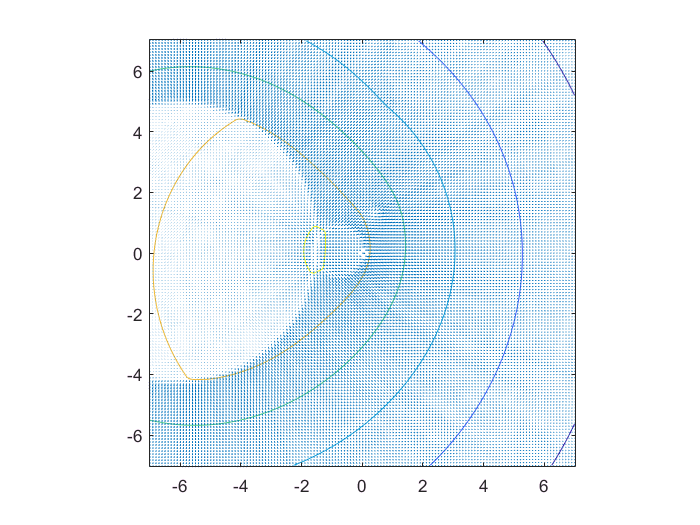


axis 'equal'

hold off

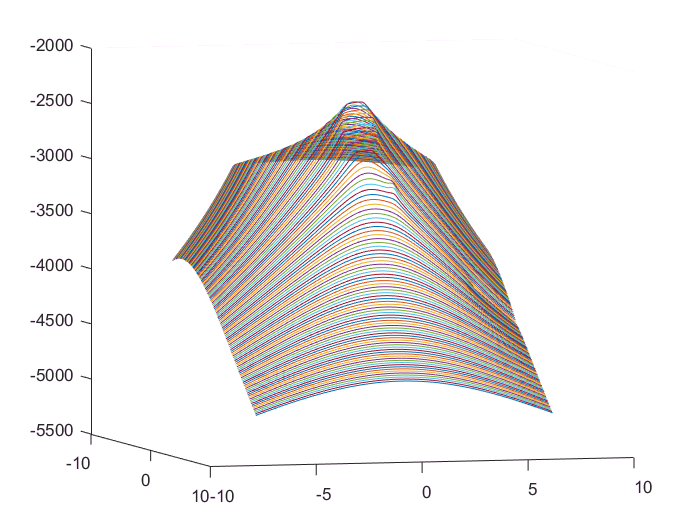

plot3(x,y,(VB+VA+V+VC+VD+VE+VF+VG+VH+VI+VJ+VK+VL+VM+VM))

for i=1:xlim
    for j=1:ylim
%this is the equation and integral with ranges for a specific object:  you
%should be able to figure out what this is and edit appropriately to get
%what you want
        dV = @(theta)  -log(sqrt((x(i,j)-RR(4)*cosd(theta)+XC(4)).^2 + (y(i,j)-RR(4)*sind(theta)- YC(4)).^2)).*RR(4);
        
       
        VO(i,j) = integral(dV,0,360);
        
        
       
    end
end
contour(x,y,VB+VA+VC+V+VD+VE+VF+VG+VH+VI+VJ+VK+VL+VM+VN)
[ExB,EyB] = gradient(VB+VA+V+VC+VD+VE+VF+VG+VH+VI+VJ+VK+VL+VM+VM);
hold on
quiver(x,y,-ExB,-EyB)
x0 = 2

x0 = 2

y0 = 0

y0 = 0

t = (x == x0) & (y == y0);
indt = find(t);
f_grad = [ExB(indt) EyB(indt)]

f_grad =   -31.7159    1.2447



axis 'equal'

hold off

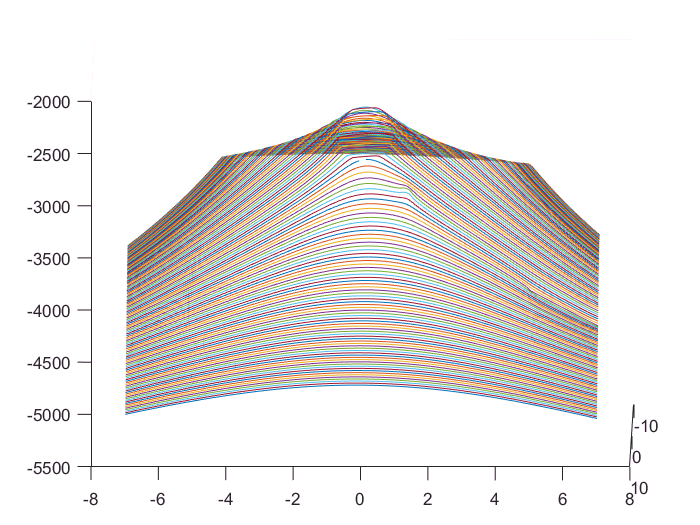

plot3(x,y,(VB+VA+V+VC+VD+VE+VF+VG+VH+VI+VJ+VK+VL+VM+VM))

sub_bump = rossubscriber('/bump');
pub = rospublisher('/raw_vel');
msg = rosmessage(pub);
  

move_dist = .35;
A = [1;0];
B = repmat(A,1,10)

B =      1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0


while 1
    for i = 1:11
       
       
        %Gradient stuff
        for g = 1:121
            for j = 1:121
                if x(g,j) == B(1, i) & y(g,j) == B(2,i)
                    tx = g
                    ty = j
                end
                
            end
        end
        
        f_grad = [ExB(tx, ty) EyB(tx, ty)]
        f_grad = f_grad/norm(f_grad)
        
        %move stuff
        psi = atan((B(2,i)-f_grad(2))/(B(1,i)-f_grad(1)))
        angle_move(.258, psi)
        forward_move(.258, move_dist)
        
        %new position
        %Rounds to closest 10ths place
        B(1,i+1) = round(B(1,i) + move_dist*cos(psi),1)
        B(2,i+1) =  round(B(2,i) + move_dist*sin(psi),1)
        % check if any of the bump sensors are set to 1 (meaning triggered)
        bumpMessage = receive(sub_bump);
        if any(bumpMessage.Data)
            msg.Data = [0.0, 0.0];
            send(pub, msg);
            break;
        end
    end
    bumpMessage = receive(sub_bump);
    if any(bumpMessage.Data)
         msg.Data = [0.0, 0.0];
         send(pub, msg);
         break;
    end
end

tx = 71

ty = 81

f_grad =   -40.0428    2.9708


f_grad =    -0.9973    0.0740


psi = -0.0370

B =     1.0000    1.3000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


B =     1.0000    1.3000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


f_grad =   -40.0428    2.9708


f_grad =    -0.9973    0.0740


psi = -0.0322

B =     1.0000    1.3000    1.6000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


B =     1.0000    1.3000    1.6000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


f_grad =   -40.0428    2.9708


f_grad =    -0.9973    0.0740


psi = -0.0285

B =     1.0000    1.3000    1.6000    1.9000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


B =     1.0000    1.3000    1.6000    1.9000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


f_grad =   -40.0428    2.9708


f_grad =    -0.9973    0.0740


psi = -0.0255

B =     1.0000    1.3000    1.6000    1.9000    2.2000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


B =     1.0000    1.3000    1.6000    1.9000    2.2000    1.0000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


f_grad =   -40.0428    2.9708


f_grad =    -0.9973    0.0740


psi = -0.0231

B =     1.0000    1.3000    1.6000    1.9000    2.2000    2.5000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0


B =     1.0000    1.3000    1.6000    1.9000    2.2000    2.5000    1.0000    1.0000    1.0000    1.0000
         0         0         0         0         0         0         0         0         0         0
